# BEV Battery Pack Plant Model

Copyright 2020-2021 The MathWorks, Inc.

## Overview

This example shows how to create a typical Battery Electric Vehicle (BEV) High Voltage (HV) Battery plant model. This figure shows the structure and the scope of the example.

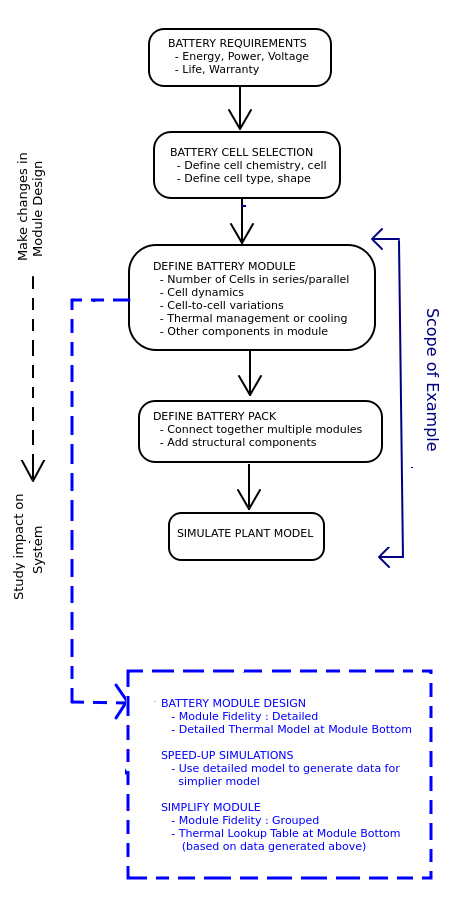

You will learn how to design a battery module, build a HV pack using the module, and run battery plant simulations.

The battery pack voltage for BEV are typically in range of 400V or higher. A single cell cannot power an entire electric vehicle. Multiple cells are connected in series and/or parallel to provide the desired energy, range, and product warranty (life). Multiple off-the-shelf battery cells are connected in series and/or parallel to form a battery module, and multiple battery modules are connected in series to form a BEV HV battery pack. 

In this example, you create a 400V battery pack by using pouch battery cells. Each battery cell is 650 mm in height, 200 mm in width and 20 mm in thickness. A battery module comprises of 15 strings of these pouch cells in series, with each string composed of 2 parallel cells. The battery module dimension is thus roughly 650 mm in height, 200 mm in width, and 600 mm in thickness (20 mm X 30 cells). Each cell nominal capacity at 25 degC is 20 A*hr. The cells are stacked together and they are liquid cooled using a cooling plate at the bottom of the module. To achieve the desired pack voltage of 400V, these modules are connected together in series.

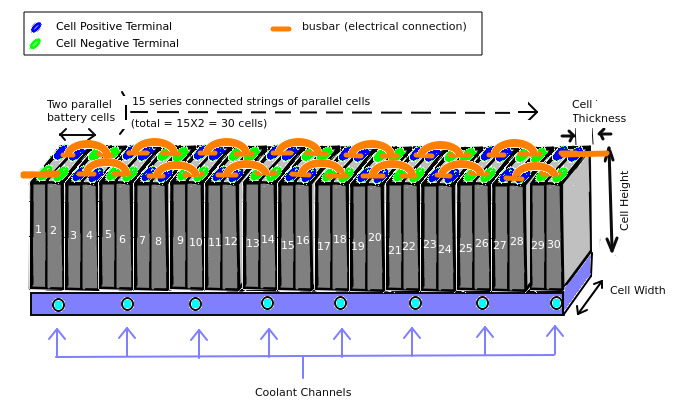

In battery simulations, to determine the next action for the Battery Management System (BMS), it is important to track the states of all cells and to find the best and the worst. A plant model that can effectively predict those state values and simulates fast is of utmost importance for the Model-Based Design of a battery. In this example, you achieve this goal by performing a detailed module design and using the simulation results from that detailed model to create a fast-simulating battery pack model using **Grouped Module** simulation fidelity.

These parameters specify the operating conditions. For a module design perspective, you must start with the worst case scenario, such as high discharge current coupled with low coolant flowrate. The current value is negative for discharge and positive for charging. The simulation end time depends on the battery cell capacity (A*hr) and the discharge rate. 

batteryCurrent=-80;       % [A]
coolantTemp=300;          % [K]
coolantMassFlowRate=0.04; % [kg/s]
ambientTemp=300;          % [K]
initialSOCvalue=0.95;     % [-]

## Battery Module Design

Battery modules are comprised of 15 strings of pouch cells in series, with each string composed of 2 parallel cells. Each cell is modeled electrically with the equivalent circuit approach using the **Battery LUT** block in Simscape(TM) Electrical(TM) library. No cell aging is considered. For more information about the parameters for the battery module, see the documentation. 

This figure shows a cooling plate that cools the module cells.

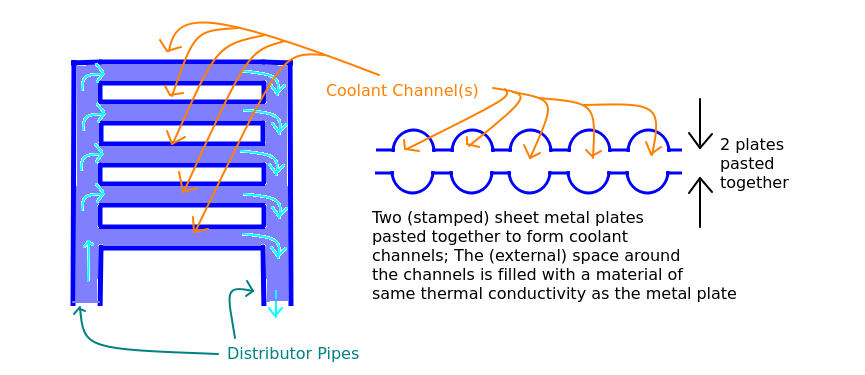

The cooling plate has channels through which the cooling liquid flows. Two stamped sheet metal components are joined together to form the cooling plate channels. The coolant plate and battery module bottom side have good thermal contact, with the gaps filled using thermally conducting material. 

This example runs simulations to determine the optimum number of parallel channels required by exploring the tradeoff between cooling plate mass and battery cell cooling efficiency. As the number of cooling plate channels increases, the cross-sectional area of the distributor inlet and the outlet pipes also increase. The channels are cylindrical and the distributor pipe has height and width associated with it. The width of the distributor channel is less than or equal to 10 mm. A thermally conductive material fills the gap between channels and battery module. The best design depends on the battery module cell-to-cell temperature gradient, mean module temperature, the pumping costs (fluid pressure drop), and the mass of the cooling plate. The cost function has weight function of [0.10 0.30 0.05 0.55] associated with these four parameters. This script determines the optimum number of channels required for the module thermal management. The **Detailed Model** fidelity, which tracks each and every cell, models the battery modules and connects it to the cooling plate using a **Detailed Thermal Model**. This connection to cooling plate component helps evaluating the cell-to-cell temperature variation with the coolant plate design. 

% Initialize Battery Module Parameters 
BEV_Battery_Plant_Model_paramModule; 
% Define Options for Number of Channels
nChannel_options=[4 8 12 16];        % array of number of channels option
coolantPlate_distributorWidMax=0.01; % max width of distributor pipe [m]
% Define Cost Function, size(1,4)
weightFraction=[0.30,... % Battery module cell-to-cell temperature gradient
                0.20,... % Mean module temperature
                0.05,... % Pumping costs (fluid pressure drop) and 
                0.45];   % Mass of the cooling plate
% Run Design Iterations to find optimum num of channels
BEV_Battery_Plant_Model_moduleDesign; 

Start module design iterations
*** Simulating for a cooling plate with 4 channels 
*** Simulating for a cooling plate with 8 channels 
*** Simulating for a cooling plate with 12 channels 
*** Simulating for a cooling plate with 16 channels 
Module design iterations Completed 
 *** Optimum number of channels = 8 


## Speedup Simulations

To make the model run faster, you can simplify the previous electro-thermal simulations. As you connect multiple modules to build a battery pack, the computational requirements increase. To reduce the model runtime, you need to extract the effective rate at which the battery cells lose heat to the coolant under different scenarios and use it as a predefined lookup table data for faster simulations. This process involves:

- Generating data for the effective rate of battery cell heat exchange under different scenarios (coolant inlet temperature and flowrates)

- Converting the detailed thermal model into a simpler thermal lookup table using the data generated in point (1) above

To generate the data required to define the **Thermal Lookup Table**, run the optimized battery module (with the **Detailed Thermal Model**) at different coolant inlet temperature and flow rates of interest. 

% Coolant inlet temperature points of interest
vec_dataLUTpts_T=[295 300 305];             % [K]
% Coolant flowrate points of interest
vec_dataLUTpts_F=[0.03 0.06 0.09 0.12];     % [kg/s]
% Data generated is valid for given AMBIENT conditions
% Data can be generated using any value of current
% It is good practise to use constant current and one
% full charge/discharge cycle
batteryCurrent=-30;       % constant current [A]
initialSOCvalue=0.99;     % fully charged cell [-]
BEV_Battery_Plant_Model_dataGenLUT;

Start data generation for Thermal LUT model
*** Simulating for flowrate = 0.03 kg/s and Temperature = 295.0 K 
*** Simulating for flowrate = 0.06 kg/s and Temperature = 295.0 K 
*** Simulating for flowrate = 0.09 kg/s and Temperature = 295.0 K 
*** Simulating for flowrate = 0.12 kg/s and Temperature = 295.0 K 
*** Simulating for flowrate = 0.03 kg/s and Temperature = 300.0 K 
*** Simulating for flowrate = 0.06 kg/s and Temperature = 300.0 K 
*** Simulating for flowrate = 0.09 kg/s and Temperature = 300.0 K 
*** Simulating for flowrate = 0.12 kg/s and Temperature = 300.0 K 
*** Simulating for flowrate = 0.03 kg/s and Temperature = 305.0 K 
*** Simulating for flowrate = 0.06 kg/s and Temperature = 305.0 K 
*** Simulating for flowrate = 0.09 kg/s and Temperature = 305.0 K 
*** Simulating for flowrate = 0.12 kg/s and Temperature = 305.0 K 
Completed data generation for Thermal LUT model


Then, use the data generated from this script to setup a faster, simpler model with similar accuracy of thermal and electrical outputs. This figure schematically shows the process:

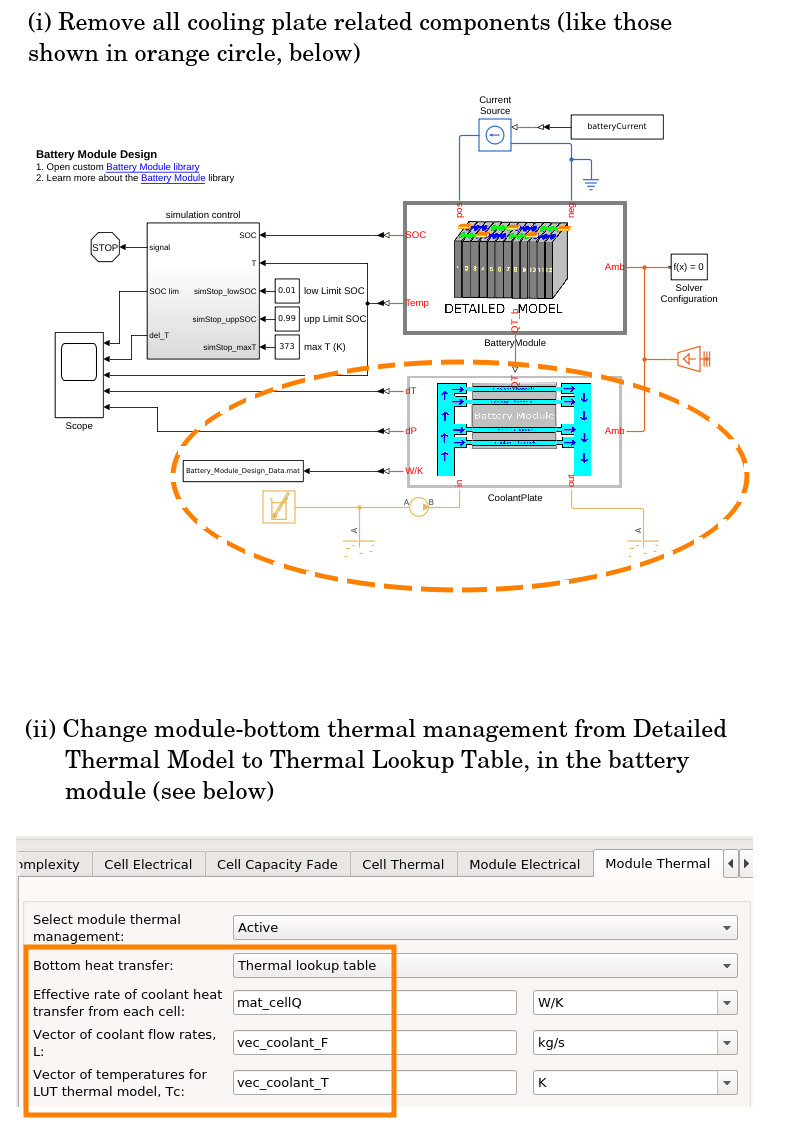

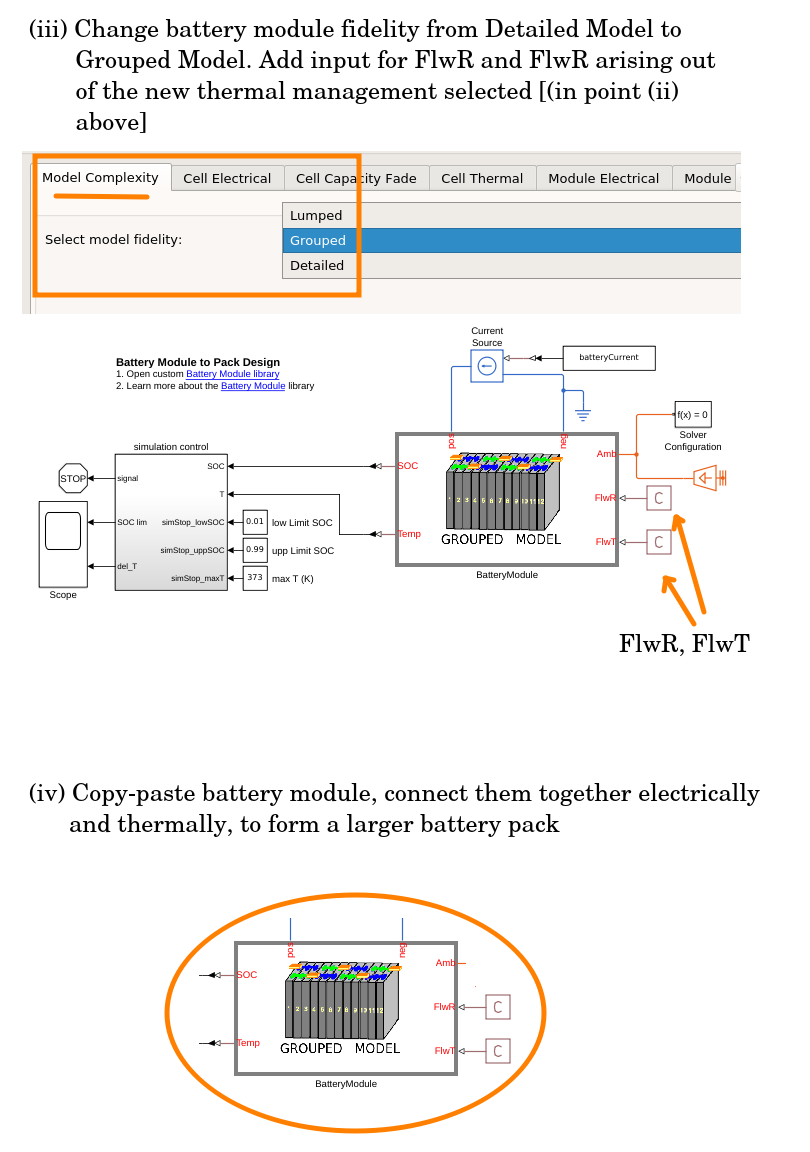

To summarize above process (in points i - iv):

- Replace the cooling plate by modifying the bottom-side cooling of the battery module from Detailed Thermal to Thermal Lookup Table

- Change the battery module fidelity from Detailed Model to the Grouped Model

This figure shows the Grouped Model fidelity:

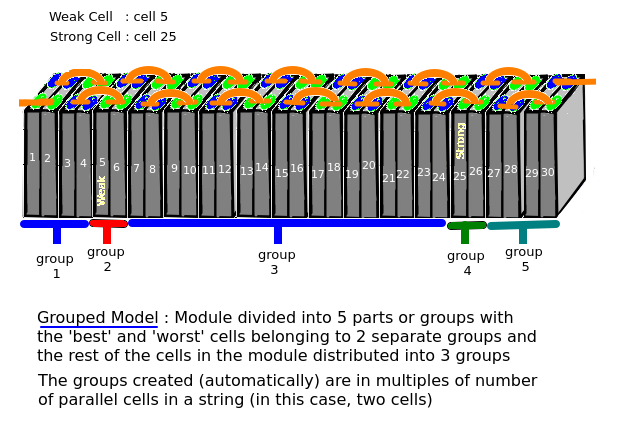

In a Grouped Model representation, the cell-to-cell variation and the module cooling parameters identify a weak and strong cell. The code (custom component) divides the module in 5 groups. The worst and best cells are in separate groups while the rest of the cells are grouped together in 3 more separate groups. These grouped elements electrically and thermally represent the module. 

## Module Verification

To verify the changes between the detailed model and the updated model, run this script:

Start Detailed to Grouped model verification
Runtime comparison 
 *** Detailed Model = 171.0 seconds 
 *** Grouped Model = 11.7 seconds 


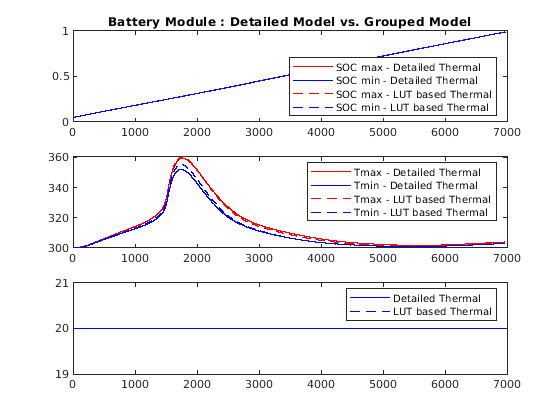

Completed model verification


batteryCurrent=20;        % [A]
initialSOCvalue=0.05;     % [-]
coolantTemp=298;          % [K]
coolantMassFlowRate=0.12; % [kg/s]
BEV_Battery_Plant_Model_moduleVerification;

To model a larger battery pack, you can assemble or connect multiple modules together.

## Define Battery Pack

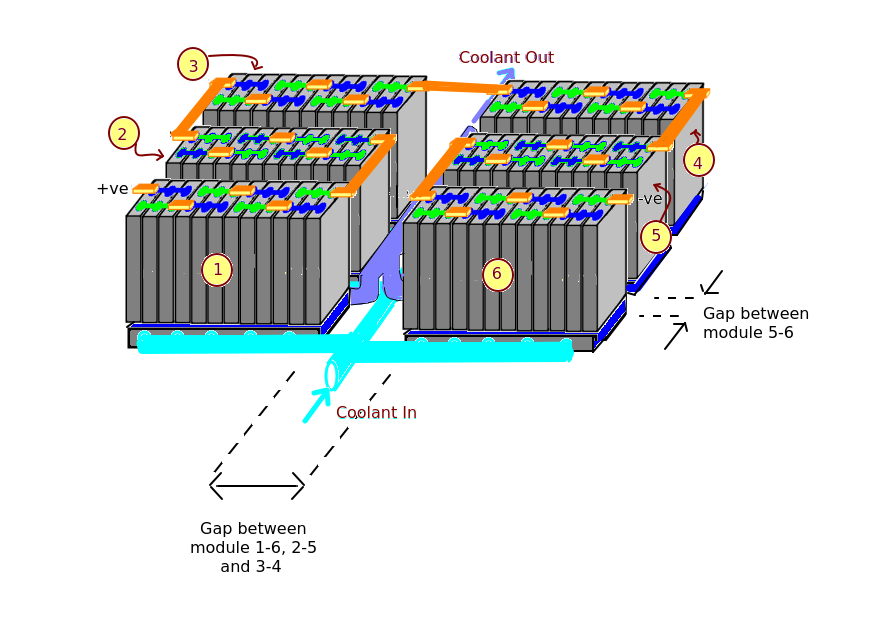

You can create a battery pack by electrically connecting 6 modules together in series. The modules, numbered 1-6, are connected in series and placed next to each other. The air gap between modules 1-2, 2-3, 4-5, 5-6 is 10 mm. The air gap between modules 1-6, 2-5, 3-4 is 50 mm. All modules receive coolant at same flowrate and temperature. Structural plastic plates then enclose the pack on all sides. The bottom side contains the cooling plate. The structural enclosure on sides and top is open to ambient.

airGapBetweenModuleSmall=0.01; % [m]
airGapBetweenModuleLarge=0.05; % [m]
endPlateThickness=0.002;       % [m]

The Simscape model shows these physical system along with the relevant electrical and thermal connections:

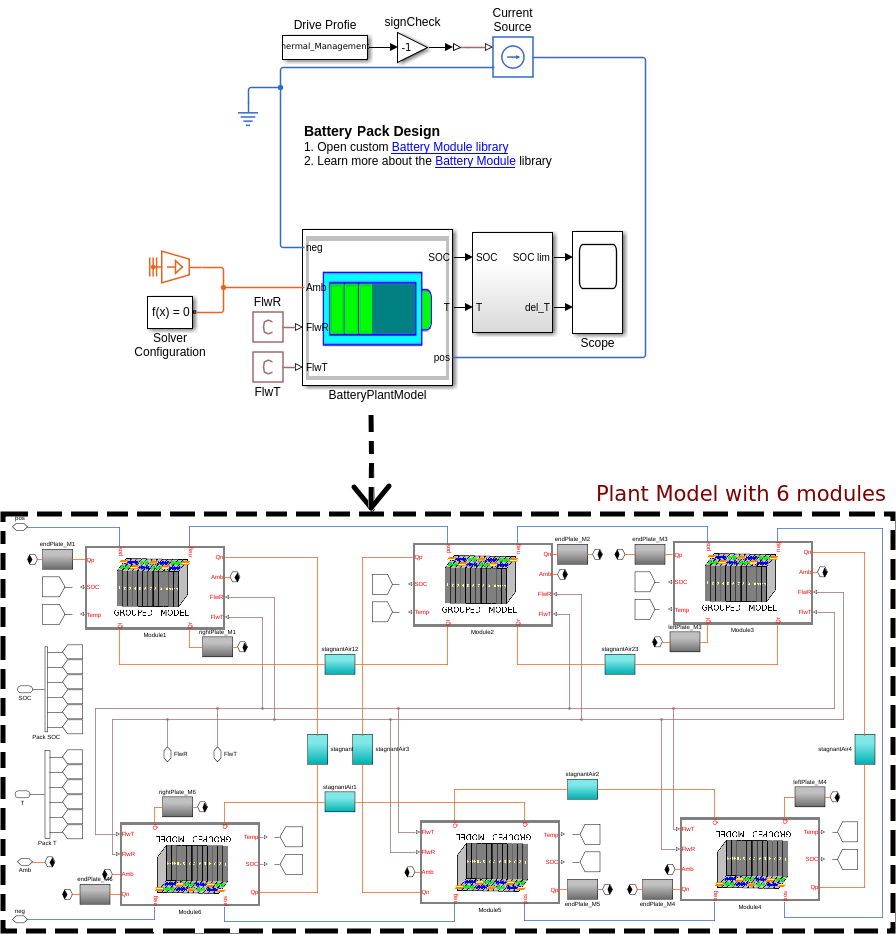

## Plant Model Simulation

The HV battery pack (~400V) consists of 180 battery cells. Each cell has a different capacity and internal resistance due to manufacturing variations. The module parameters for the minimum and maximum cell capacity and internal resistance are defined below:

% Define cell-to-cell resistance variations
batteryCell_Ahr_fracMin=0.98;
batteryCell_Ahr_fracMax=1.01;
batteryCell_R0_fracMin=0.95;
batteryCell_R0_fracMax=1.05;
BEV_Battery_Plant_Model_cellToCellVar

Setup cell-to-cell variations
Completed setup for cell-to-cell variations


The pack initial SOC (state of charge) is 75% (0.75, on a scale of 0-1) and the coolant is pumped in with a mass flow rate and temperature of 0.06 kg/s and 298 K, respectively.

initialSOCvalue=0.75;           % [-]
coolantTemp=298;                % [K]
coolantMassFlowRate=0.06;       % [kg/s]

The pack is then simulated for a drive profile for 900s.

Start battery pack simulations


*** Pack simulation runtime = 53.1 s for 

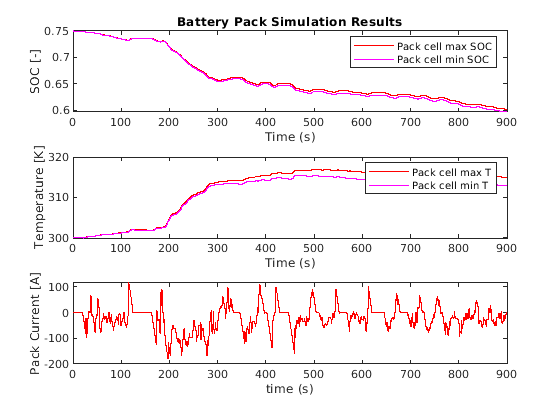

End simulations


BEV_Battery_Plant_Model_packSimulations

## Conclusion

This example shows a workflow to design a detailed battery module for a fast simulating full pack (HV pack). This example uses only one type of module, with varying cell properties. You must repeat this exercise for all modules in a pack composed of multiple different types of module (number of cells, cooling plate type). 

The detailed module design involves thermal management using the **Detailed Thermal Model.** For more information on implementation of this model, in the MATLAB command window, enter:

uiopen('detailedThermalModel_demo.slx',1)

The side(s) 1 & 2 represent Battery Custom Component and the Cooling Plate Custom Component. The test example demonstrates 2-way data exchange using signals of arbitrary size. This work-around is done due to limitations in Simscape Language related to an Array of Nodes, where the size of the array must be a parameter of pre-defined fixed size.

The **Detailed Thermal Model** allows you to exchange thermal data of each and every cell with another custom component and enables the study of temperature variations from cell-to-cell due to design changes in cooling plate. You can simplify the **Detailed Thermal Model** by processing its output in a 3D array and by providing it as an input for a simplifed version of thermal management, using lookup tables (**Thermal Lookup Table** option).